## **HCP Main Sample -  Region-Specific Coupling All Conditions - 4 Measures **

Computation of region-specific SC-FC coupling maps (measure that is able to explain the highest variance in FC across all participants most frequently) and creation of correlation matrix depicting the similarity between vectors of regional SC-FC coupling pattern. 

Before running this script: 

- run all scripts in HCP Data Prep 

**1. Create a group-average map depicting the regional SC-FC coupling pattern for each condition**

1.1.  Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:532
    x = final_r_all_HCP_wm_532{i,2};% change here to switch between the 8 conditions(rest/task) 
    for j = 1:358
    Node_all_baseline_best_measures_HCP_r2{i,j} = x(j,:);
    end
end


1.2. Create a cell containing information about all subjects and coupling measures per node

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 532*8 matrix for each node)

n = size(Node_all_baseline_best_measures_HCP_r2,2);
All_Nodes_complete_baseline_best_measures_HCP_r2 = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_best_measures_HCP_r2{j} = vertcat(Node_all_baseline_best_measures_HCP_r2{:,j});
end 

1.3. Only keep 4 measures: path length (1), communicability (2), cosine distance (3) & search information (4) 

for i = 1:358
    eight_measures_per_node = All_Nodes_complete_baseline_best_measures_HCP_r2{1,i};
    four_measures_per_node = eight_measures_per_node(:,1:4);
    All_Nodes_complete_baseline_best_measures_HCP_r2_4_measures{1,i} = four_measures_per_node;
end

1.4. Collect the highest coupling value and the respective coupling measure per node 

Max_values_individuals_HCP = zeros(532,358);
Max_indices_individuals_HCP = zeros(532,358);

for i = 1:358
    node_values = All_Nodes_complete_baseline_best_measures_HCP_r2_4_measures{1,i};

    for p = 1:532
        individual_values = node_values(p,:);
        max_r2 = max(individual_values);
        idx_max = find(individual_values == max_r2); 
        Max_values_individuals_HCP(p,i) = max_r2;
        Max_indices_individuals_HCP(p,i) = idx_max;

    end
end

1.5. Find out mode for each node (group-based mask) 

Mode_for_all_nodes = zeros(1,358);

for i = 1:358
    all_selected_measures_per_node = Max_indices_individuals_HCP(:,i);
    [mode_node,frequency_mode] = mode(all_selected_measures_per_node);
    Mode_for_all_nodes(1,i) = mode_node;
end

1.6. Extract the values per node from measure that was selected with the highest frequency (mode) and average across all participants 

Mean_values_across_all_nodes = zeros(1,358);
Stdev_values_across_all_nodes = zeros(1,358);

for i = 1:358
    
node_values = All_Nodes_complete_baseline_best_measures_HCP_r2_4_measures{1,i};
measure_highest_occurence = Mode_for_all_nodes(i);
node_values_measure_highest_occurence = node_values(:,measure_highest_occurence);

mean_per_node = mean(node_values_measure_highest_occurence);
stdev_per_node = std(node_values_measure_highest_occurence); 

Mean_values_across_all_nodes(1,i) = mean_per_node;
Stdev_values_across_all_nodes(1,i) = stdev_per_node;

end

**2. Create the brain maps (Mean)**

2.1. Convert cell to mat

Mean_values_across_all_nodes_mat = Mean_values_across_all_nodes % rename the variable here depending on condition that input data is coming from (important for the correlation matrix later)

Mean_values_across_all_nodes_mat =     0.1714    0.0633    0.1096    0.2006    0.2268    0.2248    0.1949    0.1802    0.1670    0.0430    0.0471    0.0563    0.1728    0.0660    0.0585    0.1890    0.1158    0.1393    0.2248    0.2092    0.2019    0.1972    0.0927    0.0599    0.0631    0.0683    0.0361    0.0671    0.0394    0.0622    0.0623    0.0401    0.0648    0.0803    0.0811    0.0641    0.0617    0.0400    0.0820    0.1134    0.0669    0.1251    0.0813    0.0780    0.0902    0.0919    0.1330    0.0355    0.0707    0.1045


min(Mean_values_across_all_nodes_mat)

ans = 0.0109

max(Mean_values_across_all_nodes_mat)

ans = 0.2415

2.2. Insert a 0 at node 120 & 300

a = Mean_values_across_all_nodes_mat;
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Mean_values_across_all_nodes_mat_360 = a

Mean_values_across_all_nodes_mat_360 =     0.1714    0.0633    0.1096    0.2006    0.2268    0.2248    0.1949    0.1802    0.1670    0.0430    0.0471    0.0563    0.1728    0.0660    0.0585    0.1890    0.1158    0.1393    0.2248    0.2092    0.2019    0.1972    0.0927    0.0599    0.0631    0.0683    0.0361    0.0671    0.0394    0.0622    0.0623    0.0401    0.0648    0.0803    0.0811    0.0641    0.0617    0.0400    0.0820    0.1134    0.0669    0.1251    0.0813    0.0780    0.0902    0.0919    0.1330    0.0355    0.0707    0.1045


Mean_values_across_all_nodes_mat_360(120) = NaN;
Mean_values_across_all_nodes_mat_360(300)= NaN;

2.3. Plot

annotName = 'hcp-mmp-b'

annotName = 'hcp-mmp-b'

dataVec = Mean_values_across_all_nodes_mat_360

dataVec =     0.1714    0.0633    0.1096    0.2006    0.2268    0.2248    0.1949    0.1802    0.1670    0.0430    0.0471    0.0563    0.1728    0.0660    0.0585    0.1890    0.1158    0.1393    0.2248    0.2092    0.2019    0.1972    0.0927    0.0599    0.0631    0.0683    0.0361    0.0671    0.0394    0.0622    0.0623    0.0401    0.0648    0.0803    0.0811    0.0641    0.0617    0.0400    0.0820    0.1134    0.0669    0.1251    0.0813    0.0780    0.0902    0.0919    0.1330    0.0355    0.0707    0.1045


ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [0 0.3500]
    viewcMap: 1
     viewStr: 'all'


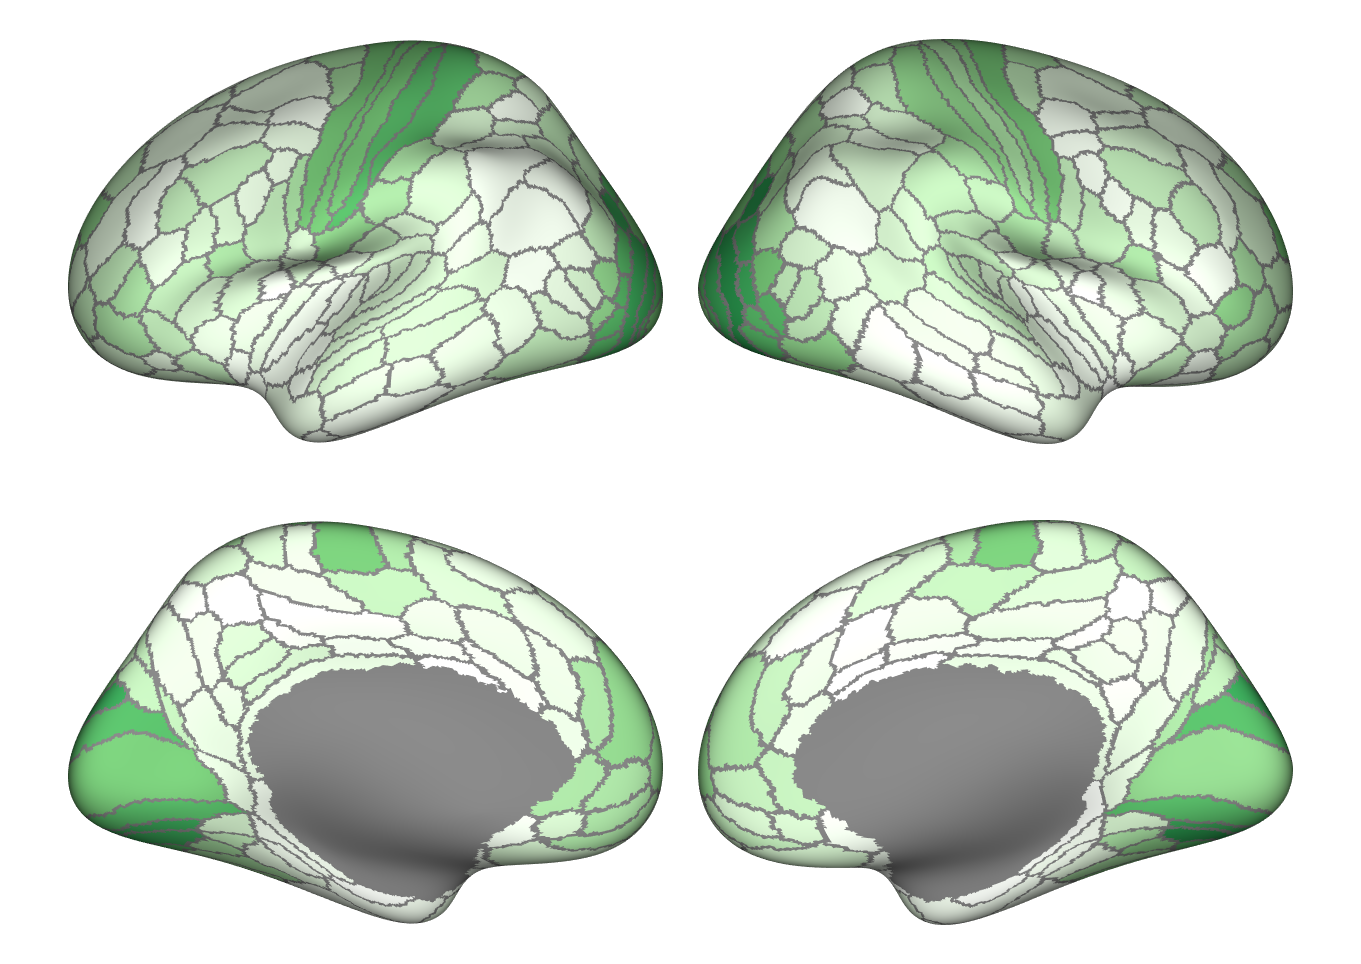

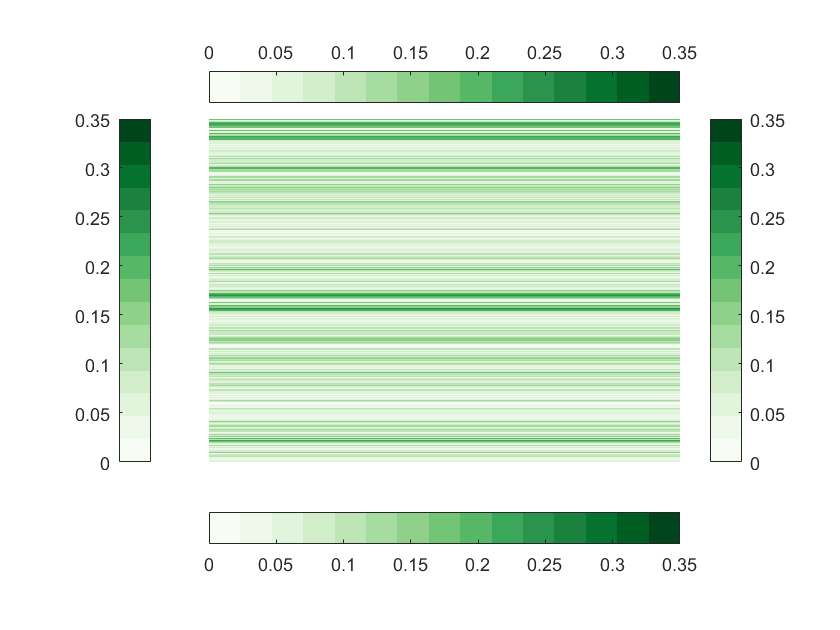

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec,'cMap',brewermap(15,'Greens'),...
    'viewcMap',1, 'valRange', ([0 0.35]))

**3. Create the brain maps (Stdev)**

3.1. Convert cell to mat

Stdev_values_across_all_nodes_mat = Stdev_values_across_all_nodes % rename the variable here depending on condition that input data is coming from (important for the correlation matrix later)

Stdev_values_across_all_nodes_mat =     0.0471    0.0363    0.0573    0.0462    0.0504    0.0509    0.0769    0.0751    0.0631    0.0402    0.0465    0.0474    0.0749    0.0374    0.0348    0.0780    0.0442    0.0527    0.0747    0.0766    0.0769    0.0756    0.0575    0.0388    0.0375    0.0510    0.0281    0.0443    0.0266    0.0358    0.0314    0.0289    0.0346    0.0368    0.0342    0.0420    0.0414    0.0338    0.0429    0.0612    0.0513    0.0557    0.0495    0.0445    0.0423    0.0381    0.0620    0.0342    0.0437    0.0375


min(Stdev_values_across_all_nodes_mat)

ans = 0.0154

max(Stdev_values_across_all_nodes_mat)

ans = 0.0808

3.2. Insert a 0 at node 120 & 300

a = Stdev_values_across_all_nodes_mat;
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Stdev_values_across_all_nodes_mat_360 = a

Stdev_values_across_all_nodes_mat_360 =     0.0471    0.0363    0.0573    0.0462    0.0504    0.0509    0.0769    0.0751    0.0631    0.0402    0.0465    0.0474    0.0749    0.0374    0.0348    0.0780    0.0442    0.0527    0.0747    0.0766    0.0769    0.0756    0.0575    0.0388    0.0375    0.0510    0.0281    0.0443    0.0266    0.0358    0.0314    0.0289    0.0346    0.0368    0.0342    0.0420    0.0414    0.0338    0.0429    0.0612    0.0513    0.0557    0.0495    0.0445    0.0423    0.0381    0.0620    0.0342    0.0437    0.0375


Stdev_values_across_all_nodes_mat_360(120) = NaN;
Stdev_values_across_all_nodes_mat_360(300)= NaN;

3.3. Plot

annotName = 'hcp-mmp-b'

annotName = 'hcp-mmp-b'

dataVec = Stdev_values_across_all_nodes_mat_360

dataVec =     0.0471    0.0363    0.0573    0.0462    0.0504    0.0509    0.0769    0.0751    0.0631    0.0402    0.0465    0.0474    0.0749    0.0374    0.0348    0.0780    0.0442    0.0527    0.0747    0.0766    0.0769    0.0756    0.0575    0.0388    0.0375    0.0510    0.0281    0.0443    0.0266    0.0358    0.0314    0.0289    0.0346    0.0368    0.0342    0.0420    0.0414    0.0338    0.0429    0.0612    0.0513    0.0557    0.0495    0.0445    0.0423    0.0381    0.0620    0.0342    0.0437    0.0375


ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [0 0.1000]
    viewcMap: 1
     viewStr: 'all'


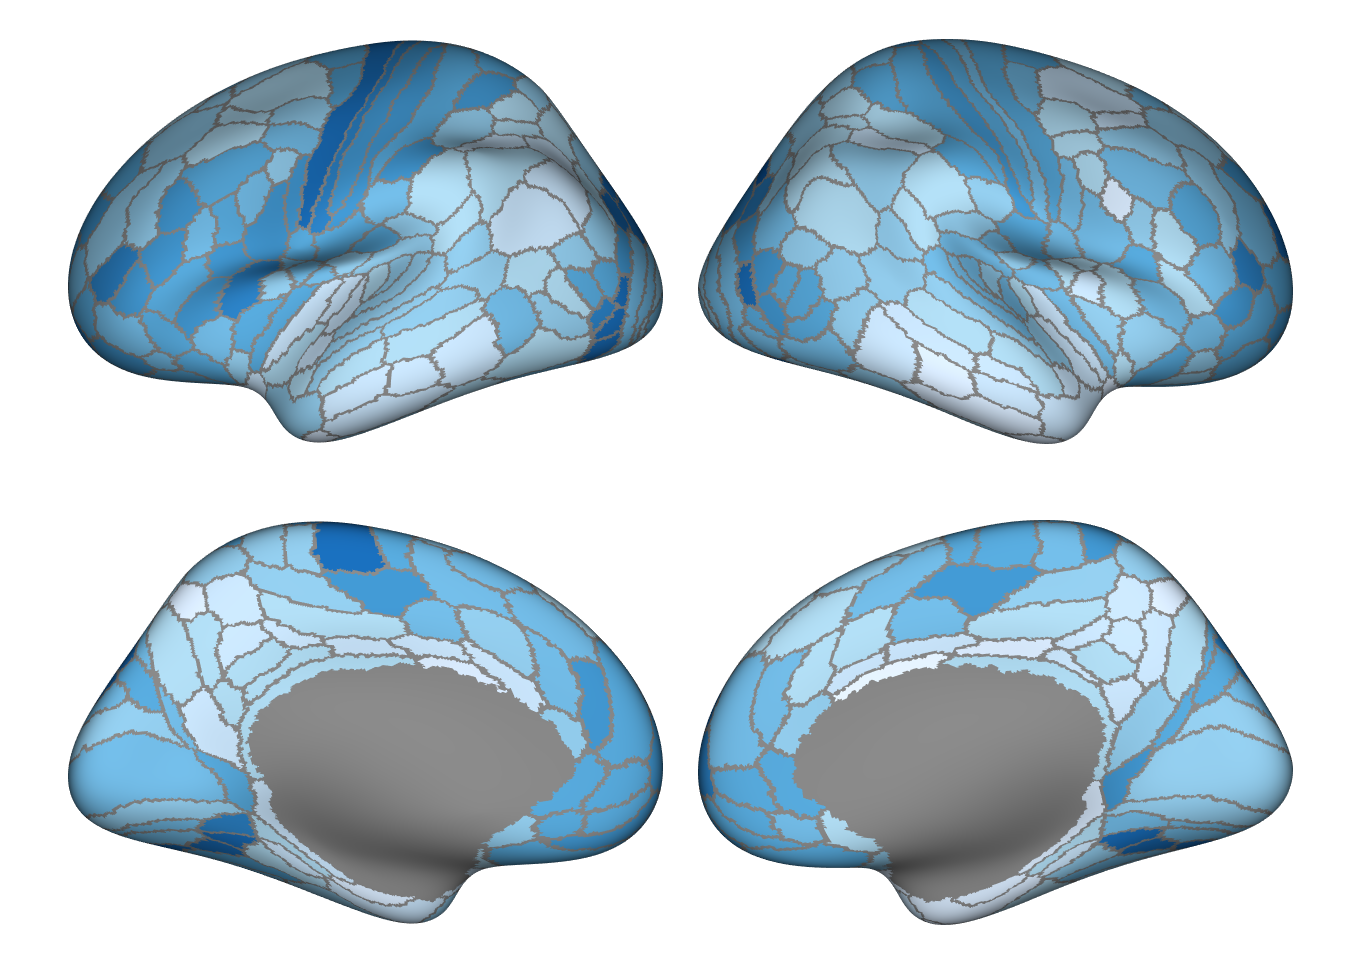

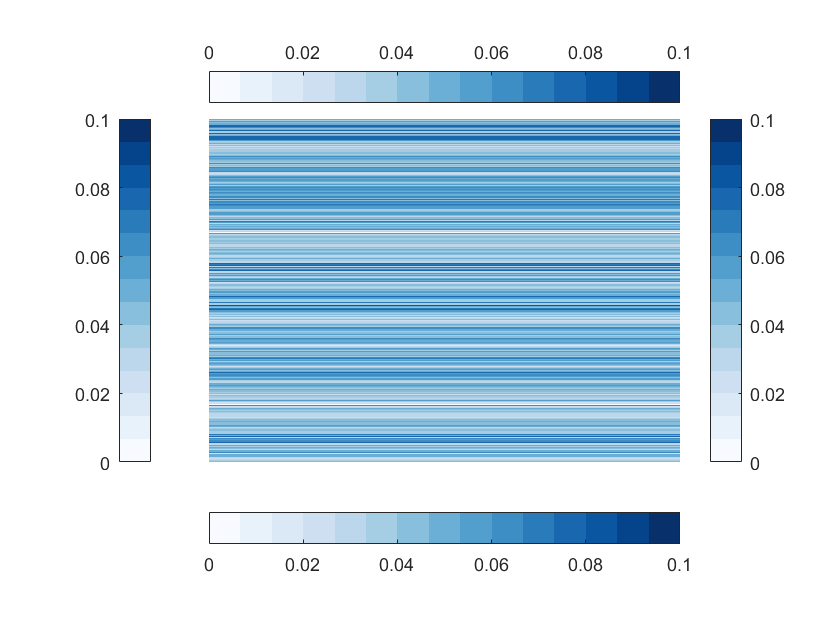

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec,'cMap',brewermap(15,'Blues'),...
    'viewcMap',1, 'valRange', ([0 0.1]))

**4. Creation of correlation matrix depicting the similarity of condition-specific SC-FC coupling patterns **

4.1. Create the correlation matrix

coupling_vectors_all_conditions = [Mean_values_across_all_nodes_rest' Mean_values_across_all_nodes_emotion' Mean_values_across_all_nodes_gambling' Mean_values_across_all_nodes_language' Mean_values_across_all_nodes_motor' Mean_values_across_all_nodes_relational' Mean_values_across_all_nodes_social' Mean_values_across_all_nodes_wm']

Unrecognized function or variable 'Mean_values_across_all_nodes_rest'.

correlation_matrix = corrcoef(coupling_vectors_all_conditions)

4.2. Plot the correlation matrix 

imagesc(correlation_matrix)
colorbar
set(gca, 'XTick', 1:8); % center x-axis ticks on bins
set(gca, 'YTick', 1:8); % center y-axis ticks on bins
xticklabels({'rest', 'emotion', 'gambling','language' ,'motor' , 'relational', 'social', 'wm'})
set(gca,'xaxisLocation','top')
yticklabels({'rest', 'emotion', 'gambling','language' ,'motor' , 'relational', 'social', 'wm'})
title('Correlation between condition-specific coupling measures', 'FontSize', 10); % set title
colormap('jet'); % Choose jet or any other color scheme